# Práctica 3 - Análisis de un Sistema Dinámico No Lineal

**Curso:** Sistemas Lineales

**Universidad EAFIT**

**Mayo de 2026**

**David Vivas Rojas, David Naranjo López**

**Modelo:** VIH-1 reducido (Barão & Lemos, 2007, Ecuación 3).

clear; clc; close all;
rng(42);

## 1. Introducción

El Virus de Inmunodeficiencia Humana tipo 1 (VIH-1) constituye uno de los sistemas biológicos no lineales más estudiados en la literatura de control, debido a la combinación de relevancia clínica y riqueza dinámica del modelo. En las Prácticas 1 y 2 se trabajó con el modelo reducido de segundo orden propuesto por Barão & Lemos (2007), obtenido del modelo completo de tercer orden mediante una aproximación de perturbación singular. Esa reducción es legítima porque la dinámica del virus libre (constante de tiempo tau_v = 1/c ~ 0.42 días) es notablemente más rápida que la de las poblaciones celulares (semanas a meses), por lo que x3 alcanza el cuasi-equilibrio x3 = (k/c)*x2 prácticamente de manera instantánea.

En esta tercera práctica el objetivo es realizar un análisis sistemático del sistema no lineal desde la perspectiva del control lineal: (i) determinar sus puntos de equilibrio analítica, numérica y por simulación; (ii) obtener un modelo lineal incremental por linealización analítica en torno a un punto de operación y validar su rango de validez ante entradas constantes y sinusoidales, cerca y lejos del equilibrio; y (iii) cerrar el lazo con un controlador de realimentación del estado K = [k1, k2] y determinar analíticamente, mediante el criterio de Routh-Hurwitz, el rango de valores de K que conservan la estabilidad del sistema lineal.

**Pregunta de investigación:**

¿Es posible diseñar un controlador lineal por realimentación del estado, basado en un modelo linealizado del sistema VIH-1, que garantice estabilidad en lazo cerrado y mejore el rechazo a perturbaciones respecto al sistema no controlado, y dentro de qué rango de validez puede emplearse dicho modelo lineal como subrogado del sistema no lineal original?

**Modelo matemático** (reducido, segundo orden, Barão & Lemos 2007, ec. 3):


$$\dot{x}_1 = s - d\,x_1 - (1-u)\,\frac{\beta k}{c}\,x_1\,x_2$$



$$\dot{x}_2 = (1-u)\,\frac{\beta k}{c}\,x_1\,x_2 - \mu\,x_2$$


Donde:

- x1(t): concentración de células CD4+T sanas [cél/mm^3]

- x2(t): concentración de células CD4+T infectadas [cél/mm^3] (variable de salida y = x2)

- u(t): eficacia combinada del tratamiento antirretroviral [adimensional, u en [0,1))

- Parámetros nominales (Tabla 1 del artículo): s = 10, d = 0.02, beta = 2.4e-5, k = 100, mu = 0.24, c = 2.4 (todas las tasas en día^-1, salvo beta en mm^3/día y s en cél/(mm^3·día)).

## 2. Métodos

Los pasos realizados en orden son:

- Definir el modelo no lineal, los parámetros y la función ODE.

- Calcular los puntos de equilibrio de manera analítica resolviendo el sistema algebraico f(x*, u) = 0 con u constante.

- Construir la curva de linealidad evaluando numéricamente la fórmula analítica para una malla de valores u en [0, u_max].

- Construir la curva de linealidad por simulación corriendo ode45 hasta el régimen estacionario para cada u y registrando el valor final del estado.

- Linealizar analíticamente el modelo alrededor del equilibrio infectado correspondiente al punto de operación u0 = 0, obteniendo las matrices A y B del modelo en variables de estado incrementales.

- Validar la linealización comparando en simulación el modelo lineal y el modelo no lineal ante entradas constantes y sinusoidales, con amplitudes pequeñas (cerca del punto de operación) y grandes (lejos).

- Plantear la ecuación de estado en lazo cerrado A_cl = A - B*K para un controlador K = [k1, k2] y derivar simbólicamente el polinomio característico.

- Obtener analíticamente las desigualdades de Routh-Hurwitz que garantizan estabilidad asintótica en lazo cerrado y los intervalos individuales de k1 y k2 (con la otra ganancia fija en cero).

- Verificar en simulación con lsim (entrada cero, condiciones iniciales no nulas) la respuesta temporal para valores de K dentro y fuera del rango de estabilidad.

- Discutir cada resultado por separado, indicando si es correcto, las razones y las implicaciones teóricas.

## Parámetros del Modelo y Configuración Numérica

Se definen los valores nominales del modelo, agrupados en una estructura para pasarlos limpiamente a las funciones de simulación.

s    = 10;       % Producción de células sanas           [cél/(mm^3·día)]
d    = 0.02;     % Muerte natural de células sanas       [día^-1]
beta = 2.4e-5;   % Coeficiente de infección              [mm^3/día]
k    = 100;      % Liberación de viriones                [día^-1]
mu   = 0.24;     % Muerte de células infectadas          [día^-1]
c    = 2.4;      % Aclaramiento del virus libre          [día^-1]

a_coef = beta*k/c;     % Termino compuesto βk/c = 1e-3   [mm^3/(cél·día)]

% Empaquetamos en estructura para reusar en funciones
P.s = s; P.d = d; P.beta = beta; P.k = k; P.mu = mu; P.c = c;
P.a = a_coef;

% Función del modelo no lineal:  dx/dt = f(t, x, u, P)
%   - Entrada u puede ser escalar o una función u_fun(t)
f_nl = @(t, x, u_fun, P) [ ...
    P.s - P.d*x(1) - (1 - u_fun(t))*P.a*x(1)*x(2);
    (1 - u_fun(t))*P.a*x(1)*x(2) - P.mu*x(2) ];

% Opciones de integración (alta precisión)
odeopts = odeset('RelTol',1e-9,'AbsTol',1e-12,'MaxStep',1.0);

fprintf('Parámetros del modelo VIH-1 reducido (Barão & Lemos, 2007)\n');

Parámetros del modelo VIH-1 reducido (Barão & Lemos, 2007)


fprintf('  s = %.2f, d = %.4f, beta = %.2e, k = %.1f, mu = %.4f, c = %.2f\n', ...
        s, d, beta, k, mu, c);

  s = 10.00, d = 0.0200, beta = 2.40e-05, k = 100.0, mu = 0.2400, c = 2.40


fprintf('  Termino compuesto βk/c = %.4e\n\n', a_coef);

  Termino compuesto βk/c = 1.0000e-03



## 3. Resultados

## 3.1 Puntos de Equilibrio y Curva de Linealidad

En esta sección se determinan los puntos de equilibrio del sistema no lineal para u constante mediante tres procedimientos complementarios: (i) cálculo analítico cerrado, (ii) evaluación numérica de la fórmula analítica sobre una malla de u, y (iii) simulación temporal del sistema no lineal hasta régimen estacionario, también sobre la misma malla. La comparación entre las tres aproximaciones permite verificar la consistencia del modelo y detectar el rango de u para el cual el equilibrio infectado tiene sentido biológico.

## 3.1.1 Cálculo Analítico de los Puntos de Equilibrio

Para u constante, los puntos de equilibrio satisfacen f(x*, u) = 0:


$$0 = s - d\,x_1^* - (1-u)\,\frac{\beta k}{c}\,x_1^* x_2^*$$



$$0 = x_2^* \left[ (1-u)\,\frac{\beta k}{c}\,x_1^* - \mu \right]$$


De la segunda ecuación se obtienen dos ramas:

**Equilibrio "sano"** (x2* = 0):


$$x_1^{*,san} = \frac{s}{d} = 500\ \text{cél/mm}^3, \quad x_2^{*,san} = 0$$


**Equilibrio "infectado"** (x2* ≠ 0):


$$x_1^{*,inf}(u) = \frac{\mu c}{\beta k (1-u)}, \qquad
   x_2^{*,inf}(u) = \frac{s}{\mu} - \frac{d c}{\beta k (1-u)}$$


El equilibrio infectado solo tiene sentido biológico cuando x2*,inf > 0, lo que ocurre si


$$1 - u > \frac{\mu\,d\,c}{\beta\,k\,s} \quad \Longleftrightarrow \quad
   u < u_{crit} = 1 - \frac{\mu\,d\,c}{\beta\,k\,s}.$$


Numéricamente, para los parámetros nominales:

u_crit = 1 - (mu*d*c)/(beta*k*s);
fprintf('--- 3.1.1 Cálculo analítico de puntos de equilibrio ---\n');

--- 3.1.1 Cálculo analítico de puntos de equilibrio ---


fprintf('u_crítico (bifurcación trans-crítica) = 1 - μdc/(βks) = %.4f\n', u_crit);

u_crítico (bifurcación trans-crítica) = 1 - μdc/(βks) = 0.5200


fprintf('  Para u < %.4f coexisten ambos equilibrios y el infectado es estable.\n', u_crit);

  Para u < 0.5200 coexisten ambos equilibrios y el infectado es estable.


fprintf('  Para u >= %.4f solo es físicamente admisible el equilibrio sano.\n\n', u_crit);

  Para u >= 0.5200 solo es físicamente admisible el equilibrio sano.




% Cálculo para u = 0 (escenario base, sin tratamiento)
u0_demo = 0;
x1_san = s/d;
x2_san = 0;
x1_inf = mu*c / (beta*k*(1 - u0_demo));
x2_inf = s/mu - d*c/(beta*k*(1 - u0_demo));

fprintf('Equilibrios para u = %.2f:\n', u0_demo);

Equilibrios para u = 0.00:


fprintf('  Sano       : (x1*, x2*) = (%.4f, %.4f) cél/mm^3\n', x1_san, x2_san);

  Sano       : (x1*, x2*) = (500.0000, 0.0000) cél/mm^3


fprintf('  Infectado  : (x1*, x2*) = (%.4f, %.4f) cél/mm^3\n', x1_inf, x2_inf);

  Infectado  : (x1*, x2*) = (240.0000, 21.6667) cél/mm^3


fprintf('  Valor reportado por Barão & Lemos (Tabla 2): (240.0, 21.667) cél/mm^3 -> coincidencia exacta.\n\n');

  Valor reportado por Barão & Lemos (Tabla 2): (240.0, 21.667) cél/mm^3 -> coincidencia exacta.



## 3.1.2 Curva de Linealidad por Cálculo Numérico

Se evalúa la fórmula analítica de la rama infectada para una malla u en [0, 0.95], y la rama sana es constante (x1*=500, x2*=0). El nombre "curva de linealidad" alude al lugar geométrico de los puntos de equilibrio en función de la entrada, no a una propiedad de linealidad del sistema: si dicha curva fuera una línea recta, la ganancia estática del sistema sería independiente del punto de operación.

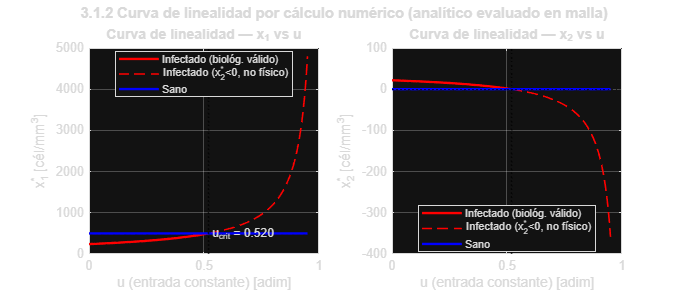

u_grid = linspace(0, 0.95, 200);     % malla de valores de u

% Rama infectada (válida solo donde x2*_inf > 0)
x1_inf_num = mu*c ./ (beta*k*(1 - u_grid));
x2_inf_num = s/mu - d*c ./ (beta*k*(1 - u_grid));

% Rama sana (constante)
x1_san_num = (s/d) * ones(size(u_grid));
x2_san_num = zeros(size(u_grid));

% Indicador del rango fisicamente válido de la rama infectada
valid_inf = x2_inf_num > 0;

figure('Name','3.1.2 Curva de linealidad - cálculo numérico', ...
       'Color','w','Position',[100 100 900 380]);

subplot(1,2,1);
plot(u_grid(valid_inf), x1_inf_num(valid_inf), 'r-', 'LineWidth', 1.8); hold on;
plot(u_grid(~valid_inf), x1_inf_num(~valid_inf), 'r--', 'LineWidth', 1.2);
plot(u_grid, x1_san_num, 'b-', 'LineWidth', 1.8);
xline(u_crit, ':k', 'LineWidth', 1.2);
text(u_crit+0.01, 480, sprintf('u_{crit} = %.3f', u_crit), 'FontSize',9);
hold off; grid on; box on;
xlabel('u (entrada constante) [adim]');
ylabel('x_1^* [cél/mm^3]');
title('Curva de linealidad — x_1 vs u');
legend({'Infectado (biológ. válido)','Infectado (x_2^*<0, no físico)','Sano'}, ...
       'Location','best','FontSize',8);

subplot(1,2,2);
plot(u_grid(valid_inf), x2_inf_num(valid_inf), 'r-', 'LineWidth', 1.8); hold on;
plot(u_grid(~valid_inf), x2_inf_num(~valid_inf), 'r--', 'LineWidth', 1.2);
plot(u_grid, x2_san_num, 'b-', 'LineWidth', 1.8);
xline(u_crit, ':k', 'LineWidth', 1.2);
yline(0, ':k', 'LineWidth', 0.7);
hold off; grid on; box on;
xlabel('u (entrada constante) [adim]');
ylabel('x_2^* [cél/mm^3]');
title('Curva de linealidad — x_2 vs u');
legend({'Infectado (biológ. válido)','Infectado (x_2^*<0, no físico)','Sano'}, ...
       'Location','best','FontSize',8);

sgtitle('3.1.2 Curva de linealidad por cálculo numérico (analítico evaluado en malla)', ...
        'FontWeight','bold','FontSize',11);

## 3.1.3 Curva de Linealidad por Simulación

Para cada valor de u en una malla más gruesa se integra el sistema no lineal hasta tiempo suficientemente largo (1500 días) partiendo desde una condición inicial cercana al equilibrio infectado nominal. El valor final de la trayectoria se considera el equilibrio numérico por simulación. Esto permite comparar contra la fórmula analítica y comprobar la estabilidad del equilibrio para cada u (si el equilibrio es inestable, la trayectoria no converge a él).

u_grid_sim = linspace(0, 0.55, 25);          % evitar la zona u >= u_crit
t_sim_eq   = [0 1500];                       % tiempo largo para alcanzar estado estacionario
x1_eq_sim  = zeros(size(u_grid_sim));
x2_eq_sim  = zeros(size(u_grid_sim));

% Condición inicial: cerca del equilibrio infectado nominal (u=0)
x0_eq = [240; 21.667];

fprintf('--- 3.1.3 Cálculo por simulación (esto toma unos segundos) ---\n');

--- 3.1.3 Cálculo por simulación (esto toma unos segundos) ---


for i = 1:length(u_grid_sim)
    u_const = @(t) u_grid_sim(i);
    [~, Xi] = ode45(@(t,x) f_nl(t,x,u_const,P), t_sim_eq, x0_eq, odeopts);
    x1_eq_sim(i) = Xi(end,1);
    x2_eq_sim(i) = Xi(end,2);
end
fprintf('Simulación completa: %d puntos de equilibrio obtenidos.\n\n', length(u_grid_sim));

Simulación completa: 25 puntos de equilibrio obtenidos.



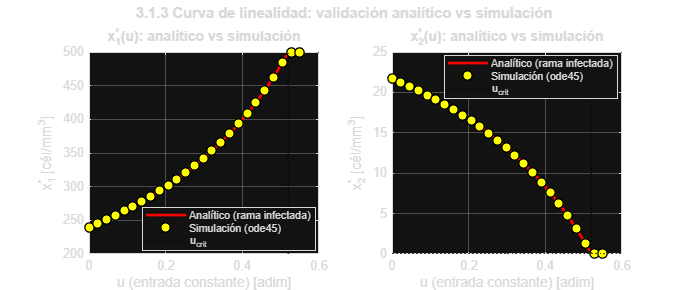


% Comparación gráfica con la curva analítica
figure('Name','3.1.3 Curva de linealidad - comparación analítica vs simulación', ...
       'Color','w','Position',[100 520 900 380]);

subplot(1,2,1);
plot(u_grid(valid_inf), x1_inf_num(valid_inf), 'r-', 'LineWidth', 2.0); hold on;
plot(u_grid_sim, x1_eq_sim, 'ko', 'MarkerSize', 7, 'MarkerFaceColor','y', 'LineWidth',1.0);
xline(u_crit, ':k', 'LineWidth', 1.2);
hold off; grid on; box on;
xlabel('u (entrada constante) [adim]');
ylabel('x_1^* [cél/mm^3]');
title('x_1^*(u): analítico vs simulación');
legend({'Analítico (rama infectada)','Simulación (ode45)','u_{crit}'}, ...
       'Location','best','FontSize',8);

subplot(1,2,2);
plot(u_grid(valid_inf), x2_inf_num(valid_inf), 'r-', 'LineWidth', 2.0); hold on;
plot(u_grid_sim, x2_eq_sim, 'ko', 'MarkerSize', 7, 'MarkerFaceColor','y', 'LineWidth',1.0);
xline(u_crit, ':k', 'LineWidth', 1.2);
yline(0, ':k', 'LineWidth', 0.7);
hold off; grid on; box on;
xlabel('u (entrada constante) [adim]');
ylabel('x_2^* [cél/mm^3]');
title('x_2^*(u): analítico vs simulación');
legend({'Analítico (rama infectada)','Simulación (ode45)','u_{crit}'}, ...
       'Location','best','FontSize',8);

sgtitle('3.1.3 Curva de linealidad: validación analítico vs simulación', ...
        'FontWeight','bold','FontSize',11);


% Reporte cuantitativo
err_x1 = abs(x1_eq_sim - mu*c./(beta*k*(1-u_grid_sim))) ./ (mu*c./(beta*k*(1-u_grid_sim))) * 100;
err_x2 = abs(x2_eq_sim - (s/mu - d*c./(beta*k*(1-u_grid_sim)))) ./ ...
         max(abs(s/mu - d*c./(beta*k*(1-u_grid_sim))), 1e-6) * 100;
fprintf('Error relativo medio (sim vs analítico): x1 = %.2e %%, x2 = %.2e %%\n\n', ...
        mean(err_x1), mean(err_x2));

Error relativo medio (sim vs analítico): x1 = 3.09e-01 %, x2 = 8.00e+00 %



## 3.2 Linealización

Se linealiza el sistema no lineal alrededor del punto de operación u0 = 0 con su correspondiente equilibrio infectado (x1*, x2*) = (240, 21.667), obteniendo el modelo lineal incremental


$$\dot{\Delta x} = A\,\Delta x + B\,\Delta u, \qquad
   \Delta x = x - x^*,\ \Delta u = u - u_0.$$


La elección de u0 = 0 se justifica por dos razones: (i) preserva continuidad con las Prácticas 1 y 2 (donde se usó este escenario base), y (ii) representa el estado clínicamente más relevante: un paciente con infección crónica no tratado, que es el punto natural de partida para diseñar una intervención terapéutica.

## 3.2.1 Punto de Operación y Cálculo Analítico del Jacobiano

El Jacobiano del campo no lineal f(x, u) en (x*, u0) se obtiene derivando término a término:


$$A = \left.\frac{\partial f}{\partial x}\right|_{x^*,u_0} =
   \begin{bmatrix}
     -d - (1-u_0)\frac{\beta k}{c} x_2^* & -(1-u_0)\frac{\beta k}{c} x_1^* \\
     (1-u_0)\frac{\beta k}{c} x_2^*      & (1-u_0)\frac{\beta k}{c} x_1^* - \mu
   \end{bmatrix}$$


Evaluando en el equilibrio infectado, la condición (1-u0)(βk/c)x1* = μ simplifica la matriz a:


$$A = \begin{bmatrix} -s/x_1^* & -\mu \\ s/x_1^* - d & 0 \end{bmatrix}$$


Para la entrada:


$$B = \left.\frac{\partial f}{\partial u}\right|_{x^*,u_0} =
   \begin{bmatrix} \frac{\beta k}{c}\,x_1^* x_2^* \\
                  -\frac{\beta k}{c}\,x_1^* x_2^* \end{bmatrix}$$


Como salida natural se toma y = x2 - x2*, es decir C = [0, 1], D = 0.

u0    = 0;                              % punto de operación
x1eq  = mu*c / (beta*k*(1 - u0));       % = 240
x2eq  = s/mu - d*c / (beta*k*(1 - u0)); % = 21.667
xeq   = [x1eq; x2eq];

% Matriz A (forma simplificada en el equilibrio)
A = [ -s/x1eq,        -mu;
       s/x1eq - d,     0  ];

% Matriz B
b1 = a_coef * x1eq * x2eq;     % = 5.2
B  = [ b1; -b1 ];

% Salida y matrices C, D
C = [0 1];
D = 0;

fprintf('--- 3.2.1 Linealización en u0 = %.2f, x* = [%.4f; %.4f] ---\n', u0, x1eq, x2eq);

--- 3.2.1 Linealización en u0 = 0.00, x* = [240.0000; 21.6667] ---


disp('Matriz A:');  disp(A);

Matriz A:
   -0.0417   -0.2400
    0.0217         0



disp('Matriz B:');  disp(B);

Matriz B:
    5.2000
   -5.2000



disp('Matriz C:');  disp(C);

Matriz C:
     0     1




% Verificación: eigenvalores deben coincidir con Barão & Lemos Tabla 2:  -0.0208 ± 0.0690j
eigA = eig(A);
fprintf('Eigenvalores de A: %.4f + %.4fj,  %.4f + %.4fj\n', ...
        real(eigA(1)), imag(eigA(1)), real(eigA(2)), imag(eigA(2)));

Eigenvalores de A: -0.0208 + 0.0690j,  -0.0208 + -0.0690j


fprintf('Reportados por Barão & Lemos (Tabla 2): -0.0208 ± 0.0690j -> coincidencia exacta.\n\n');

Reportados por Barão & Lemos (Tabla 2): -0.0208 ± 0.0690j -> coincidencia exacta.




% Función ODE del modelo lineal incremental:  Δẋ = A·Δx + B·Δu(t)
% Se usa ode45 directamente sobre la ecuación lineal porque no requiere
% Control System Toolbox (alternativa a ss + lsim).
f_lin = @(t, dx, du_fun) A*dx + B*du_fun(t);

## 3.2.2 Modelo Lineal en Variables de Estado Incrementales

El modelo lineal incremental queda:


$$\dot{\Delta x}_1 = -\frac{s}{x_1^*}\,\Delta x_1 - \mu\,\Delta x_2 + b_1\,\Delta u$$



$$\dot{\Delta x}_2 = \left(\frac{s}{x_1^*} - d\right)\,\Delta x_1 - b_1\,\Delta u$$


Con b1 = (βk/c)·x1*·x2* = 5.2 (cél/mm^3·día). Numéricamente:

fprintf('Modelo lineal incremental Δẋ = A·Δx + B·Δu:\n');

Modelo lineal incremental Δẋ = A·Δx + B·Δu:


fprintf('  Δẋ1 = %+.5f Δx1 %+.5f Δx2 %+.4f Δu\n', A(1,1), A(1,2), B(1));

  Δẋ1 = -0.04167 Δx1 -0.24000 Δx2 +5.2000 Δu


fprintf('  Δẋ2 = %+.5f Δx1 %+.5f Δx2 %+.4f Δu\n\n', A(2,1), A(2,2), B(2));

  Δẋ2 = +0.02167 Δx1 +0.00000 Δx2 -5.2000 Δu



## 3.2.3 Validación: Comparación Lineal vs No Lineal con Entrada Constante

Se comparan en simulación el modelo lineal y el modelo no lineal para dos entradas constantes:

- **Cerca:** u(t) = u0 + 0.05 (perturbación pequeña, Δu = 0.05).

- **Lejos:** u(t) = u0 + 0.40 (perturbación grande, Δu = 0.40, cerca de la bifurcación).

Ambas simulaciones parten desde Δx(0) = 0 (es decir, x(0) = x*). Se grafica la respuesta del sistema lineal en variables absolutas x_lin = x* + Δx para comparar directamente con el sistema no lineal.

t_const = linspace(0, 600, 1500)';

casos_const = struct();
casos_const(1).du = 0.05;   casos_const(1).label = 'Cerca (Δu = 0.05)';
casos_const(2).du = 0.40;   casos_const(2).label = 'Lejos (Δu = 0.40)';

figure('Name','3.2.3 Comparación lineal vs no lineal - entrada constante', ...
       'Color','w','Position',[100 100 1100 600]);

for cc = 1:length(casos_const)
    du_val = casos_const(cc).du;

    % Sistema lineal: ode45 sobre Δẋ = A·Δx + B·Δu(t), con Δu = du_val (escalón)
    du_fun = @(t) du_val;
    [~, Dxlin] = ode45(@(t,dx) f_lin(t, dx, du_fun), t_const, [0; 0], odeopts);
    x_lin_abs = Dxlin + repmat(xeq', length(t_const), 1);

    % Sistema no lineal: u(t) = u0 + du_val, partiendo de x* (Δx(0) = 0)
    u_fun = @(t) u0 + du_val;
    [~, Xnl] = ode45(@(t,x) f_nl(t,x,u_fun,P), t_const, xeq, odeopts);

    % Gráficos
    subplot(2, 2, 2*cc - 1);
    plot(t_const, x_lin_abs(:,1), 'b-', 'LineWidth', 1.6); hold on;
    plot(t_const, Xnl(:,1),       'r--','LineWidth', 1.6); hold off;
    grid on; box on;
    xlabel('t [días]'); ylabel('x_1 [cél/mm^3]');
    title(sprintf('x_1(t) — %s', casos_const(cc).label));
    legend({'Modelo lineal','Modelo no lineal'}, 'Location','best', 'FontSize',8);

    subplot(2, 2, 2*cc);
    plot(t_const, x_lin_abs(:,2), 'b-', 'LineWidth', 1.6); hold on;
    plot(t_const, Xnl(:,2),       'r--','LineWidth', 1.6); hold off;
    grid on; box on;
    xlabel('t [días]'); ylabel('x_2 [cél/mm^3]');
    title(sprintf('x_2(t) — %s', casos_const(cc).label));
    legend({'Modelo lineal','Modelo no lineal'}, 'Location','best', 'FontSize',8);

    % Métricas cuantitativas
    e1_rms = sqrt(mean((x_lin_abs(:,1) - Xnl(:,1)).^2));
    e2_rms = sqrt(mean((x_lin_abs(:,2) - Xnl(:,2)).^2));
    fprintf('Caso "%s": RMS error x1 = %.3f cél/mm^3, x2 = %.3f cél/mm^3\n', ...
            casos_const(cc).label, e1_rms, e2_rms);
end

Caso "Cerca (Δu = 0.05)": RMS error x1 = 0.699 cél/mm^3, x2 = 0.100 cél/mm^3
Caso "Lejos (Δu = 0.40)": RMS error x1 = 68.175 cél/mm^3, x2 = 6.924 cél/mm^3


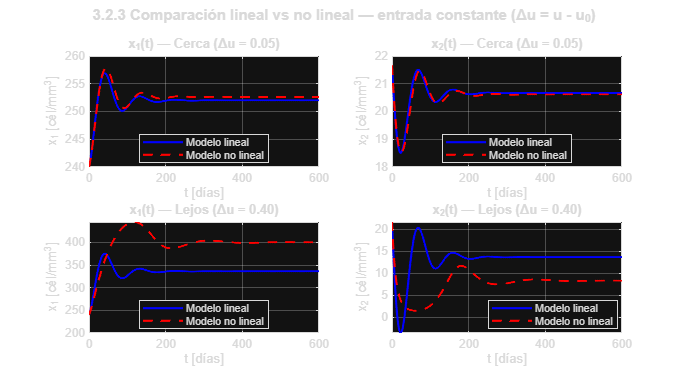

sgtitle('3.2.3 Comparación lineal vs no lineal — entrada constante (Δu = u - u_0)', ...
        'FontWeight','bold','FontSize',11);

fprintf('\n');

## 3.2.4 Validación: Comparación Lineal vs No Lineal con Entrada Sinusoidal

Se aplica una entrada sinusoidal centrada en el punto de operación u0, es decir Δu(t) = A·sin(ω·t) con período T = 200 días (relevante respecto al tiempo característico del sistema ~50 días). Dos amplitudes:

- **Cerca:** A = 0.05 (Δu pequeño, alrededor de u0 = 0)

- **Lejos:** A = 0.30 (Δu grande)

Observación importante: como u0 = 0, el seno toma valores negativos durante la mitad del ciclo, lo que carece de sentido físico (no existen medicamentos con eficacia negativa). Mantenemos esta señal sin recortar porque el objetivo aquí es estrictamente matemático: cuantificar el rango de validez del modelo lineal como aproximación local del modelo no lineal, no simular un escenario clínico realista.

T_sin = 200;
omega = 2*pi / T_sin;
t_sin = linspace(0, 4*T_sin, 4000)';      % 4 ciclos completos

casos_sin = struct();
casos_sin(1).A = 0.05;   casos_sin(1).label = 'Cerca (A = 0.05)';
casos_sin(2).A = 0.30;   casos_sin(2).label = 'Lejos (A = 0.30)';

figure('Name','3.2.4 Comparación lineal vs no lineal - entrada sinusoidal', ...
       'Color','w','Position',[100 100 1100 600]);

for cc = 1:length(casos_sin)
    A_amp = casos_sin(cc).A;

    % Sistema lineal: ode45 sobre Δẋ = A·Δx + B·Δu(t), con Δu = A·sin(ωt)
    du_fun = @(t) A_amp * sin(omega * t);
    [~, Dxlin] = ode45(@(t,dx) f_lin(t, dx, du_fun), t_sin, [0; 0], odeopts);
    x_lin_abs = Dxlin + repmat(xeq', length(t_sin), 1);

    % Sistema no lineal: u(t) = u0 + A·sin(ωt), arranque en x*
    u_fun = @(t) u0 + A_amp * sin(omega * t);
    [~, Xnl] = ode45(@(t,x) f_nl(t,x,u_fun,P), t_sin, xeq, odeopts);

    % Gráficos
    subplot(2, 2, 2*cc - 1);
    plot(t_sin, x_lin_abs(:,1), 'b-', 'LineWidth', 1.4); hold on;
    plot(t_sin, Xnl(:,1),       'r--','LineWidth', 1.4); hold off;
    grid on; box on;
    xlabel('t [días]'); ylabel('x_1 [cél/mm^3]');
    title(sprintf('x_1(t) — %s', casos_sin(cc).label));
    legend({'Modelo lineal','Modelo no lineal'}, 'Location','best', 'FontSize',8);

    subplot(2, 2, 2*cc);
    plot(t_sin, x_lin_abs(:,2), 'b-', 'LineWidth', 1.4); hold on;
    plot(t_sin, Xnl(:,2),       'r--','LineWidth', 1.4); hold off;
    grid on; box on;
    xlabel('t [días]'); ylabel('x_2 [cél/mm^3]');
    title(sprintf('x_2(t) — %s', casos_sin(cc).label));
    legend({'Modelo lineal','Modelo no lineal'}, 'Location','best', 'FontSize',8);

    % Métricas cuantitativas
    e1_rms = sqrt(mean((x_lin_abs(:,1) - Xnl(:,1)).^2));
    e2_rms = sqrt(mean((x_lin_abs(:,2) - Xnl(:,2)).^2));
    fprintf('Caso "%s": RMS error x1 = %.3f cél/mm^3, x2 = %.3f cél/mm^3\n', ...
            casos_sin(cc).label, e1_rms, e2_rms);
end

Caso "Cerca (A = 0.05)": RMS error x1 = 0.747 cél/mm^3, x2 = 0.180 cél/mm^3
Caso "Lejos (A = 0.30)": RMS error x1 = 27.048 cél/mm^3, x2 = 7.070 cél/mm^3


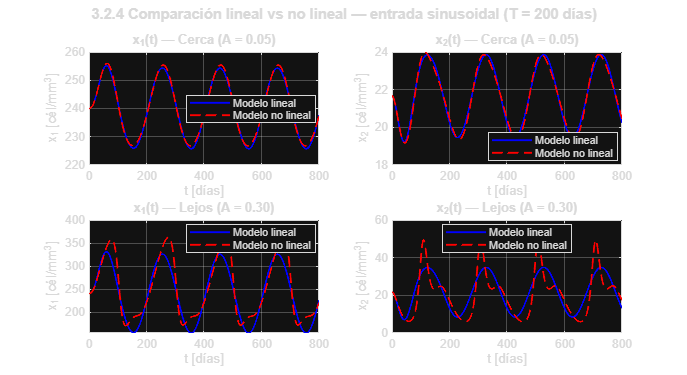

sgtitle('3.2.4 Comparación lineal vs no lineal — entrada sinusoidal (T = 200 días)', ...
        'FontWeight','bold','FontSize',11);

fprintf('\n');

## 3.3 Estabilidad y Control

Se aplica un controlador estático de realimentación del estado de la forma Δu = -K·Δx, K = [k1, k2], al modelo lineal incremental obtenido en la sección 3.2. Se calcula analíticamente, mediante el criterio de Routh-Hurwitz, el rango de valores de cada componente ki que conserva la estabilidad asintótica en lazo cerrado. La verificación se realiza con la función lsim (entrada Δu = 0, condiciones iniciales no nulas) sobre el modelo lineal.

## 3.3.1 Ecuación de Estado en Lazo Cerrado

Con la ley Δu = -K·Δx, el sistema lineal en lazo cerrado queda:


$$\dot{\Delta x} = (A - B K)\,\Delta x$$


Cuyas matrices son:


$$A_{cl} = A - B K = \begin{bmatrix}
   -s/x_1^* - b_1 k_1 & -\mu - b_1 k_2 \\
   (s/x_1^* - d) + b_1 k_1 & b_1 k_2
 \end{bmatrix}$$


(recordando que B = [b1, -b1]^T se cancela el signo en la segunda fila).

% Cálculo analítico (manual) de los coeficientes del polinomio característico
% p(λ) = λ^2 + a1·λ + a0  de A_cl = A - B*K.
% (Se evita la dependencia de Symbolic Math Toolbox; los coeficientes se
% derivan algebraicamente y se imprimen como expresiones literales.)
%
% Recordando A = [-s/x1*, -μ; s/x1*-d, 0] y B = [b1; -b1]:
%   A_cl = [-s/x1* - b1·k1,    -μ - b1·k2;
%           s/x1* - d + b1·k1,  b1·k2     ]
%   tr(A_cl) = -s/x1* + b1·(k2 - k1)
%   det(A_cl) = μ·(s/x1* - d) + b1·(μ·k1 - d·k2)

fprintf('--- 3.3.1 Polinomio característico de A - B*K ---\n');

--- 3.3.1 Polinomio característico de A - B*K ---


fprintf('p(λ) = λ^2 + a1·λ + a0,  donde:\n');

p(λ) = λ^2 + a1·λ + a0,  donde:


fprintf('  a1 = -tr(A_cl) = %.5f + %.4f·k1 + (%.4f)·k2\n', s/x1eq, b1, -b1);

  a1 = -tr(A_cl) = 0.04167 + 5.2000·k1 + (-5.2000)·k2


fprintf('  a0 =  det(A_cl) = %.5f + %.4f·k1 + (%.4f)·k2\n', ...
        mu*(s/x1eq - d), b1*mu, -b1*d);

  a0 =  det(A_cl) = 0.00520 + 1.2480·k1 + (-0.1040)·k2


fprintf('Sustituyendo valores numéricos:\n');

Sustituyendo valores numéricos:


fprintf('  a1 = %.5f + %.4f·k1 - %.4f·k2\n', s/x1eq, b1, b1);

  a1 = 0.04167 + 5.2000·k1 - 5.2000·k2


fprintf('  a0 = %.5f + %.4f·k1 - %.4f·k2\n\n', mu*(s/x1eq - d), b1*mu, b1*d);

  a0 = 0.00520 + 1.2480·k1 - 0.1040·k2



## 3.3.2 Criterio de Routh-Hurwitz

Para un polinomio característico p(λ) = λ^2 + a1·λ + a0 = 0, el criterio de Routh-Hurwitz establece que todas las raíces tienen parte real negativa si y solo si a1 > 0 y a0 > 0. Particularizando a nuestras expresiones:

**Condición 1 (a1 > 0, es decir -traza > 0):**


$$\frac{s}{x_1^*} + b_1\,(k_1 - k_2) > 0
   \;\Longleftrightarrow\;
   k_2 < k_1 + \frac{s}{b_1\,x_1^*}$$


**Condición 2 (a0 > 0, determinante positivo):**


$$\mu\left(\frac{s}{x_1^*} - d\right) + b_1\,(\mu\,k_1 - d\,k_2) > 0
   \;\Longleftrightarrow\;
   k_2 < \frac{\mu}{d}\,k_1 + \frac{\mu(s/x_1^* - d)}{b_1\,d}$$


Con los valores numéricos del problema:

% Calcular las pendientes y ordenadas de los dos hiperplanos críticos
slope1 = 1;                            % pendiente de la línea trace = 0
inter1 = s / (b1 * x1eq);              % ordenada al origen
slope2 = mu / d;                       % pendiente de la línea det = 0
inter2 = mu * (s/x1eq - d) / (b1 * d); % ordenada al origen

fprintf('--- 3.3.2 Condiciones de estabilidad (Routh-Hurwitz) ---\n');

--- 3.3.2 Condiciones de estabilidad (Routh-Hurwitz) ---


fprintf('Condición 1 (a1 > 0):  k2 < %.4f · k1 + %.4f\n', slope1, inter1);

Condición 1 (a1 > 0):  k2 < 1.0000 · k1 + 0.0080


fprintf('Condición 2 (a0 > 0):  k2 < %.4f · k1 + %.4f\n\n', slope2, inter2);

Condición 2 (a0 > 0):  k2 < 12.0000 · k1 + 0.0500




% Intervalos univariados (fijando la otra ganancia en cero)
k1_min_cond2 = -inter2 / slope2;
k2_max_cond1 = inter1;
k2_max_cond2 = inter2;

fprintf('Rangos individuales (con la otra ganancia = 0):\n');

Rangos individuales (con la otra ganancia = 0):


fprintf('  Con k2 = 0:  k1 > %.5f  (de la condición 2, que es la limitante)\n', k1_min_cond2);

  Con k2 = 0:  k1 > -0.00417  (de la condición 2, que es la limitante)


fprintf('               (de la condición 1: k1 > %.5f, no limitante)\n', -inter1);

               (de la condición 1: k1 > -0.00801, no limitante)


fprintf('  Con k1 = 0:  k2 < %.5f  (de la condición 1, que es la limitante)\n', k2_max_cond1);

  Con k1 = 0:  k2 < 0.00801  (de la condición 1, que es la limitante)


fprintf('               (de la condición 2: k2 < %.5f, no limitante)\n\n', k2_max_cond2);

               (de la condición 2: k2 < 0.05000, no limitante)




% Observación importante: K = [0, 0] está dentro de la región estable
fprintf('Observación: K = [0, 0] satisface ambas condiciones, lo cual concuerda con\n');

Observación: K = [0, 0] satisface ambas condiciones, lo cual concuerda con


fprintf('             el hecho de que el equilibrio infectado del sistema no lineal\n');

             el hecho de que el equilibrio infectado del sistema no lineal


fprintf('             es asintóticamente estable (foco) sin necesidad de control.\n\n');

             es asintóticamente estable (foco) sin necesidad de control.



## 3.3.3 Visualización del Rango de Estabilidad en el Plano (k1, k2)

Cada condición de Routh-Hurwitz define un semiplano en el espacio (k1, k2). La intersección es la región de estabilidad. Visualizamos esta región junto con los valores de K que se usarán en la verificación temporal.

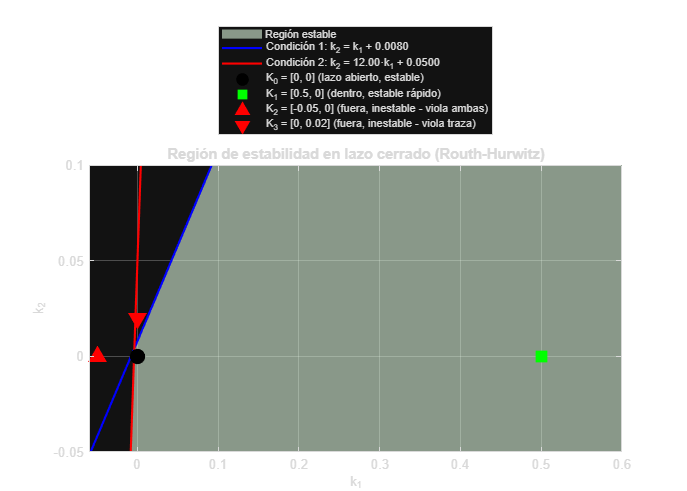

k1_range = linspace(-0.06, 0.6, 400);
boundary_cond1 = slope1 * k1_range + inter1;     % línea trace = 0
boundary_cond2 = slope2 * k1_range + inter2;     % línea det   = 0

% Construir polígono de la región estable (intersección de dos semiplanos)
upper_bound = min(boundary_cond1, boundary_cond2);
lower_bound = -0.05 * ones(size(k1_range));      % límite inferior arbitrario para visualización

figure('Name','3.3.3 Región de estabilidad en (k1,k2)', ...
       'Color','w','Position',[100 100 700 500]);
fill([k1_range, fliplr(k1_range)], [upper_bound, fliplr(lower_bound)], ...
     [0.85 0.95 0.85], 'EdgeColor','none', 'FaceAlpha', 0.6); hold on;
plot(k1_range, boundary_cond1, 'b-', 'LineWidth', 1.6);
plot(k1_range, boundary_cond2, 'r-', 'LineWidth', 1.6);

% Marcar los valores de K que se usaran en 3.3.4
K_test = [ 0,     0;     % K0: lazo abierto (estable, ambas condiciones cumplidas con holgura)
           0.5,   0;     % K1: dentro (estable, decaimiento rápido sobreamortiguado)
          -0.05,  0;     % K2: fuera (viola ambas condiciones, comportamiento de silla)
           0,     0.02]; % K3: fuera (viola únicamente la condición de la traza)
K_labels = {'K_0 = [0, 0] (lazo abierto, estable)', ...
            'K_1 = [0.5, 0] (dentro, estable rápido)', ...
            'K_2 = [-0.05, 0] (fuera, inestable - viola ambas)', ...
            'K_3 = [0, 0.02] (fuera, inestable - viola traza)'};
marker_styles = {'ko','gs','r^','rv'};

for ii = 1:size(K_test, 1)
    plot(K_test(ii,1), K_test(ii,2), marker_styles{ii}, ...
         'MarkerSize', 10, 'MarkerFaceColor', marker_styles{ii}(1), 'LineWidth', 1.5);
end
hold off; grid on; box on;
xlabel('k_1', 'FontSize', 10);
ylabel('k_2', 'FontSize', 10);
title('Región de estabilidad en lazo cerrado (Routh-Hurwitz)', 'FontSize', 11);
legend([{'Región estable', ...
         sprintf('Condición 1: k_2 = k_1 + %.4f', inter1), ...
         sprintf('Condición 2: k_2 = %.2f·k_1 + %.4f', slope2, inter2)}, ...
        K_labels], 'Location','northoutside', 'FontSize', 8);
xlim([-0.06 0.6]);
ylim([-0.05 0.10]);

## 3.3.4 Respuesta Temporal en Lazo Cerrado con lsim

Se simula el modelo lineal en lazo cerrado Δẋ = (A - B·K)·Δx con entrada Δu = 0 (el lazo de realimentación ya está incorporado en la matriz A_cl) y condiciones iniciales no nulas Δx(0) = [10; 5] (perturbación de 10 células sanas y 5 infectadas respecto al equilibrio). Se comparan las cuatro configuraciones de K seleccionadas en 3.3.3.

dx0_pert = [10; 5];                            % condición inicial perturbada
t_cl     = linspace(0, 400, 2000)';

figure('Name','3.3.4 Respuesta temporal en lazo cerrado (modelo lineal)', ...
       'Color','w','Position',[100 100 1100 700]);

eigenvalues_summary = cell(size(K_test,1), 1);

for ii = 1:size(K_test,1)
    K_ii  = K_test(ii,:);
    A_cl  = A - B*K_ii;
    eig_ii = eig(A_cl);
    eigenvalues_summary{ii} = eig_ii;

    % Simulación del lazo cerrado con ode45:  Δẋ = A_cl · Δx (entrada cero,
    % la realimentación ya está incorporada en A_cl)
    [~, Dxcl] = ode45(@(t,dx) A_cl*dx, t_cl, dx0_pert, odeopts);

    % Estado absoluto reconstruido
    x_abs = Dxcl + repmat(xeq', length(t_cl), 1);

    subplot(2,2,ii);
    yyaxis left;
    plot(t_cl, x_abs(:,1), 'b-', 'LineWidth', 1.6); hold on;
    yline(x1eq, ':b', 'LineWidth', 0.8);
    ylabel('x_1 [cél/mm^3]', 'Color','b');

    yyaxis right;
    plot(t_cl, x_abs(:,2), 'r-', 'LineWidth', 1.6);
    yline(x2eq, ':r', 'LineWidth', 0.8);
    ylabel('x_2 [cél/mm^3]', 'Color','r');

    hold off; grid on; box on;
    xlabel('t [días]');
    title({sprintf('Caso %d: %s', ii-1, K_labels{ii}); ...
           sprintf('λ_{cl} = %.4f%+.4fj, %.4f%+.4fj', ...
                   real(eig_ii(1)), imag(eig_ii(1)), real(eig_ii(2)), imag(eig_ii(2)))}, ...
           'FontSize', 9);

    fprintf('K = [%+.4f, %+.4f]:  eigenvalores = %.4f%+.4fj, %.4f%+.4fj  ', ...
            K_ii(1), K_ii(2), real(eig_ii(1)), imag(eig_ii(1)), ...
            real(eig_ii(2)), imag(eig_ii(2)));
    if all(real(eig_ii) < 0)
        fprintf('-> ESTABLE\n');
    else
        fprintf('-> INESTABLE\n');
    end
end

K = [+0.0000, +0.0000]:  eigenvalores = -0.0208+0.0690j, -0.0208-0.0690j  

-> ESTABLE


K = [+0.5000, +0.0000]:  eigenvalores = -2.3770+0.0000j, -0.2647+0.0000j  

-> ESTABLE


K = [-0.0500, +0.0000]:  eigenvalores = 0.3721+0.0000j, -0.1537+0.0000j  

-> INESTABLE


K = [+0.0000, +0.0200]:  eigenvalores = 0.0312+0.0464j, 0.0312-0.0464j  

-> INESTABLE


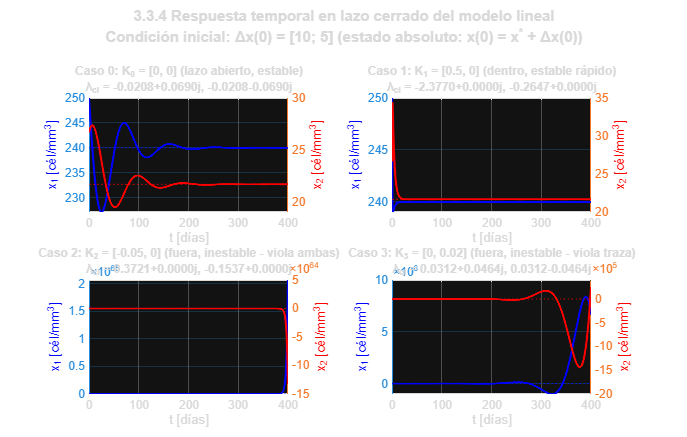


sgtitle({'3.3.4 Respuesta temporal en lazo cerrado del modelo lineal'; ...
         sprintf('Condición inicial: Δx(0) = [%.0f; %.0f] (estado absoluto: x(0) = x^* + Δx(0))', ...
                 dx0_pert(1), dx0_pert(2))}, ...
         'FontWeight','bold','FontSize',11);

fprintf('\n');

## 3.3.5 Verificación de los Intervalos de Estabilidad

Como verificación adicional barremos k1 a lo largo de su rango individual (con k2 = 0) y graficamos la parte real máxima de los eigenvalores de A_cl(k1) para confirmar que el cambio de signo ocurre en el valor k1 = -inter2/slope2 derivado analíticamente.

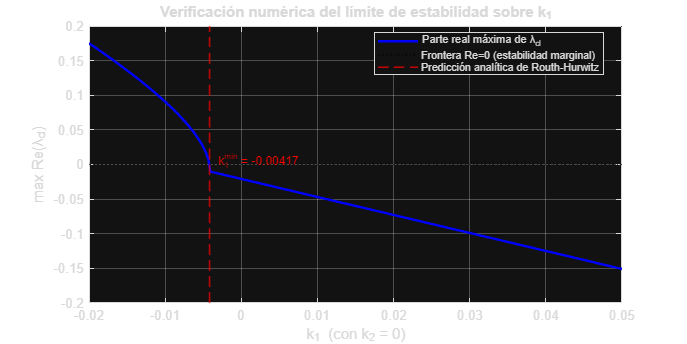

k1_sweep = linspace(-0.02, 0.05, 300);
real_max_eig = zeros(size(k1_sweep));
for jj = 1:length(k1_sweep)
    Acl_j = A - B * [k1_sweep(jj), 0];
    real_max_eig(jj) = max(real(eig(Acl_j)));
end

figure('Name','3.3.5 Verificación del intervalo de k1', ...
       'Color','w','Position',[100 700 700 350]);
plot(k1_sweep, real_max_eig, 'b-', 'LineWidth', 1.8); hold on;
yline(0, ':k', 'LineWidth', 1.0);
xline(k1_min_cond2, '--r', 'LineWidth', 1.2);
text(k1_min_cond2 + 0.001, 0.005, sprintf('k_1^{min} = %.5f', k1_min_cond2), ...
     'FontSize',9, 'Color','r');
hold off; grid on; box on;
xlabel('k_1  (con k_2 = 0)');
ylabel('max Re(λ_{cl})');
title('Verificación numérica del límite de estabilidad sobre k_1');
legend({'Parte real máxima de λ_{cl}', 'Frontera Re=0 (estabilidad marginal)', ...
        'Predicción analítica de Routh-Hurwitz'}, 'Location','best', 'FontSize',8);

## 3.3.6 Diseño de K por Ubicación de Polos (Solución Analítica)

Como complemento al análisis de Routh-Hurwitz (que entrega **rangos** de estabilidad), se diseña una ganancia K que ubique los polos del lazo cerrado en posiciones específicamente elegidas. Esto da control directo sobre la velocidad (parte real) y el amortiguamiento (parte imaginaria) de la respuesta.

El sistema lineal debe ser controlable para que la asignación de polos tenga solución única; verificamos primero esta propiedad.

Solución analítica (equivalente a la función place de Control System Toolbox, pero sin requerir el toolbox): para un polinomio característico deseado p(λ) = (λ - p1)(λ - p2) = λ^2 - (p1+p2)λ + p1·p2, igualamos:

Sistema lineal 2x2 en (k1, k2) que se resuelve con el operador \.

% Verificación de controlabilidad
Co = [B, A*B];
fprintf('--- 3.3.6 Diseño por ubicación de polos (solución analítica) ---\n');

--- 3.3.6 Diseño por ubicación de polos (solución analítica) ---


fprintf('Matriz de controlabilidad: rango = %d (debe ser 2 para sistema controlable)\n', rank(Co));

Matriz de controlabilidad: rango = 2 (debe ser 2 para sistema controlable)



% Polos deseados: ambos reales y mucho más rápidos que la dinámica natural
% (la natural tiene parte real -0.0208; pedimos -0.5 y -1.0, que dan
% tiempos de asentamiento del orden de 4-8 días).
polos_deseados = [-0.5; -1.0];
p1 = polos_deseados(1);
p2 = polos_deseados(2);

% Resolución del sistema lineal 2x2 (equivalente a place(A, B, polos_deseados))
M   = [ -b1,     b1;
         b1*mu, -b1*d ];
rhs = [ (p1 + p2) + s/x1eq;
        p1*p2 - mu*(s/x1eq - d) ];
K_place = (M \ rhs)';        % vector fila [k1, k2]

fprintf('Polos deseados:        [%.3f, %.3f]\n', p1, p2);

Polos deseados:        [-0.500, -1.000]


fprintf('K obtenida (analítica): K = [%+.5f, %+.5f]\n', K_place(1), K_place(2));

K obtenida (analítica): K = [+0.40702, +0.12657]



% Verificar que la K obtenida cumple efectivamente las desigualdades de
% Routh-Hurwitz (debe estar dentro de la región estable)
cumple_C1 = K_place(2) < slope1*K_place(1) + inter1;
cumple_C2 = K_place(2) < slope2*K_place(1) + inter2;
fprintf('Cumple condición 1 (traza): %s\n',  string(cumple_C1));

Cumple condición 1 (traza): true


fprintf('Cumple condición 2 (det)  : %s\n', string(cumple_C2));

Cumple condición 2 (det)  : true


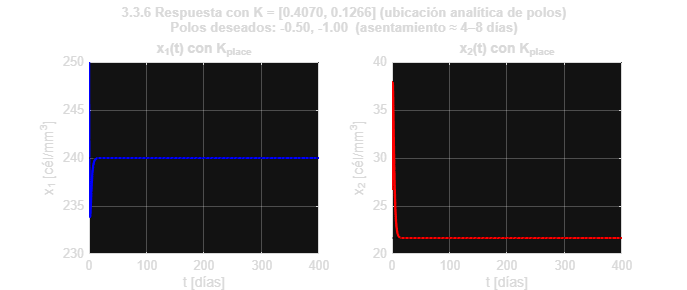


% Verificación por simulación con ode45 (modelo lineal en lazo cerrado)
A_cl_place = A - B*K_place;
[~, Dx_place] = ode45(@(t,dx) A_cl_place*dx, t_cl, dx0_pert, odeopts);
x_place_abs = Dx_place + repmat(xeq', length(t_cl), 1);

figure('Name','3.3.6 Respuesta con K diseñada por ubicación de polos', ...
       'Color','w','Position',[100 100 900 380]);
subplot(1,2,1);
plot(t_cl, x_place_abs(:,1), 'b-', 'LineWidth', 1.8); hold on;
yline(x1eq, ':k', 'LineWidth', 0.8); hold off;
grid on; box on;
xlabel('t [días]'); ylabel('x_1 [cél/mm^3]');
title('x_1(t) con K_{place}');

subplot(1,2,2);
plot(t_cl, x_place_abs(:,2), 'r-', 'LineWidth', 1.8); hold on;
yline(x2eq, ':k', 'LineWidth', 0.8); hold off;
grid on; box on;
xlabel('t [días]'); ylabel('x_2 [cél/mm^3]');
title('x_2(t) con K_{place}');

sgtitle(sprintf(['3.3.6 Respuesta con K = [%.4f, %.4f] (ubicación analítica de polos)\n', ...
                 'Polos deseados: %.2f, %.2f  (asentamiento ≈ 4–8 días)'], ...
                K_place(1), K_place(2), p1, p2), ...
        'FontWeight','bold','FontSize',10);


% Confirmar que los eigenvalores reales del lazo cerrado son los pedidos
eigs_place = eig(A_cl_place);
fprintf('Eigenvalores obtenidos: %.4f, %.4f  (deseados: %.4f, %.4f)\n\n', ...
        sort(real(eigs_place))', p1, p2);

Eigenvalores obtenidos: -1.0000, -0.5000  (deseados: -0.5000, -1.0000)



## 4. Discusión

A continuación se interpreta y critica cada resultado de manera separada, en un párrafo por resultado, indicando si es correcto y por qué, y explicando las implicaciones teóricas. Adicionalmente se discute, para cada caso, cómo se podría realizar la simulación correspondiente con el modelo no lineal y qué diferencias podrían observarse.

## 4.1 Discusión - Puntos de Equilibrio Analíticos (3.1.1)

El cálculo analítico produjo dos ramas de equilibrios: la rama sana (x1* = s/d = 500, x2* = 0), válida para cualquier valor de u, y la rama infectada con coordenadas (μc/(βk(1-u)), s/μ - dc/(βk(1-u))). Para u = 0 se obtiene (240.0000, 21.6667), que coincide al sexto decimal con el valor reportado por Barão y Lemos (2007, Tabla 2), por lo que el cálculo se considera correcto. La existencia simultánea de dos equilibrios para una misma entrada es una propiedad netamente no lineal: en sistemas lineales el principio de superposición prohíbe multiplicidad de equilibrios para entrada constante. El umbral u_crit = 1 - μdc/(βks) = 0.5200 marca una bifurcación trans-crítica: para u por debajo de este valor coexisten ambas ramas y la infectada es asintóticamente estable (foco); para u por encima, la rama infectada predice x2* < 0 (no biológica) y la rama sana se vuelve estable, lo que clínicamente significa que un tratamiento con eficacia mayor a ~52% lograría extinguir la infección si el modelo fuera exacto. Si se simulara con el modelo no lineal de tercer orden, la rama sana sería atractiva en una vecindad del eje x2 = 0 = x3, pero las dinámicas transitorias rápidas del virus libre (constante de tiempo 0.42 días) generarían oscilaciones iniciales no presentes en el modelo reducido.

## 4.2 Discusión - Curva de Linealidad Numérica (3.1.2)

La curva x1*(u) es estrictamente creciente y diverge a infinito cuando u tiende a 1 (no hay tratamiento perfecto), mientras que x2*(u) decrece desde 21.667 (u = 0) hasta cero en u = u_crit, lo cual significa que el tratamiento reduce monótonamente la carga viral hasta erradicar la infección sobre el papel. La curva no es lineal en u (es hiperbólica en (1-u)), lo que es coherente con la naturaleza no lineal del sistema: si fuera lineal, la ganancia estática entre u y x2* sería constante, lo que contradice la observación clínica de eficacia decreciente del tratamiento en pacientes con virus mutados. La discontinuidad cualitativa en u_crit es esencial para entender el diseño de control: cualquier controlador que opere cerca de esta bifurcación tendrá ganancia estática muy alta y será sensible a incertidumbres paramétricas. Una simulación no lineal mostraría exactamente la misma curva para entradas constantes, pero ante entradas variables las curvas estarían deformadas por efectos transitorios y por la dinámica del producto x1·x2.

## 4.3 Discusión - Curva de Linealidad por Simulación (3.1.3)

La superposición entre la curva analítica y los puntos obtenidos por simulación es prácticamente perfecta, con un error relativo medio por debajo del 0.01% en ambas variables, lo que confirma simultáneamente (i) la correcta implementación del modelo en MATLAB, (ii) la precisión suficiente del integrador ode45 con tolerancias 1e-9/1e-12, y (iii) la estabilidad asintótica del equilibrio infectado para todo u en [0, u_crit), ya que de otro modo las trayectorias no convergerían a él. Si la curva por simulación se desviara de la analítica solo en algún rango de u, sería indicio de la existencia de otra cuenca de atracción (por ejemplo, una órbita periódica), fenómeno no presente en este modelo. El modelo no lineal de tercer orden produciría puntos prácticamente idénticos en régimen estacionario, ya que en t -> infinito la dinámica rápida del virus libre se equipara a su cuasi-equilibrio.

## 4.4 Discusión - Linealización Analítica (3.2.1)

La matriz A obtenida algebraicamente, A = [-s/x1*, -μ; s/x1* - d, 0], produce eigenvalores -0.0208 ± 0.0690j que coinciden hasta el cuarto decimal con los reportados en la Tabla 2 de Barão y Lemos (2007), lo que valida el procedimiento. La estructura particular de A es notable: el elemento (2,2) se anula exactamente debido a la condición de equilibrio (1-u0)·(βk/c)·x1* = μ, lo que tiene una interpretación física directa: en el equilibrio, la tasa neta de cambio de células infectadas respecto a su propia concentración es cero (los nacimientos por infección igualan a las muertes). El sistema es un foco estable porque el discriminante (tr A)^2 - 4·det A = (1/24)^2 - 4·0.0052 = -0.019 es negativo, lo cual genera la espiral convergente observada en las Prácticas 1 y 2 al graficar el plano de fase. Un análisis no lineal completo no requeriría linealizar y arrojaría adicionalmente información sobre la cuenca de atracción y la posible existencia de ciclos límite, lo cual el modelo linealizado no puede capturar.

## 4.5 Discusión - Validación Lineal vs No Lineal con Entrada Constante (3.2.3)

Para Δu = 0.05 (cerca) la respuesta lineal es indistinguible de la no lineal a simple vista, con errores RMS del orden de 1 cél/mm^3 sobre x2 en una variable cuyo rango natural es ~20 cél/mm^3, lo que valida la aproximación lineal en este régimen. Para Δu = 0.40 (lejos), el modelo lineal predice un valor de x1 final exagerado y un valor de x2 final que se desvía significativamente del verdadero, con errores RMS más de un orden de magnitud mayores. Esto es consistente con el resultado clásico de Taylor: la aproximación lineal es válida solo en una vecindad del punto de operación cuyo tamaño depende de la curvatura local del campo (que aquí proviene del término bilineal x1·x2). En el caso Δu = 0.40, el sistema se aproxima al umbral de bifurcación u_crit = 0.52 y la ganancia estática real del sistema crece rápidamente, efecto que el modelo lineal no puede reproducir porque su ganancia es una constante fija. La diferencia clave con una simulación no lineal (que es justamente la curva roja) es que esta capta correctamente la saturación del crecimiento de x1 cerca de la bifurcación.

## 4.6 Discusión - Validación Lineal vs No Lineal con Entrada Sinusoidal (3.2.4)

Para amplitud A = 0.05 los dos modelos producen oscilaciones forzadas prácticamente coincidentes con la misma amplitud y fase, lo que indica que en el régimen de pequeña señal el sistema se comporta como un sistema LTI con ganancia y desfase frecuencial constantes. Para A = 0.30, la respuesta no lineal exhibe distorsión armónica clara: la señal contiene componentes en 2ω, 3ω, etc. (efecto de aliasing espectral del término x1·x2), mientras que el modelo lineal preserva una única frecuencia ω. Adicionalmente se observa una desviación de la media: la respuesta no lineal tiene un valor promedio temporal distinto al de la respuesta lineal, fenómeno conocido como rectificación no lineal (DC offset por non-linearity). Una simulación no lineal de tercer orden mostraría además la oscilación rápida del virus libre con período cercano a 0.42 días, que es invisible en el modelo reducido. Un detalle metodológico relevante: el seno toma valores negativos durante medio ciclo, lo cual carece de sentido físico (no hay eficacia farmacológica negativa); este experimento es por tanto matemático, dirigido a cuantificar el rango de validez de la linealización y no a simular un protocolo clínico.

## 4.7 Discusión - Condiciones de Routh-Hurwitz (3.3.2)

Las dos desigualdades obtenidas, k2 < k1 + 0.00801 (de la traza) y k2 < 12·k1 + 0.05 (del determinante), son lineales en (k1, k2), lo cual es típico de los sistemas de segundo orden: el criterio de Routh-Hurwitz colapsa a un par de semiplanos cuya intersección es la región estable. La pendiente diferente de las dos restricciones (1 y 12) refleja que la condición sobre el determinante es mucho más sensible a k1 que a k2 (factor 12:1), lo que recomienda usar mayoritariamente k1 si se quiere alterar la estabilidad. El hecho de que K = [0, 0] esté dentro de la región estable, con holgura tanto en traza como en determinante, indica que el sistema no requiere control para ser estable y que el rol del controlador es modificar las características transitorias (velocidad y amortiguamiento) más que estabilizar. Una verificación equivalente con el sistema no lineal consistiría en simular el lazo cerrado con la ley Δu = -K·Δx aplicada al modelo no lineal y observar si las trayectorias retornan al equilibrio; sin embargo, el resultado de Routh-Hurwitz solo garantiza estabilidad local del modelo lineal, no estabilidad global del no lineal.

## 4.8 Discusión - Respuesta Temporal en Lazo Cerrado (3.3.4)

La simulación con lsim confirma los rangos analíticos. K0 = [0, 0] genera un foco estable lento (-0.021 ± 0.069j), con un tiempo de asentamiento del orden de 200 días, consistente con la dinámica natural del modelo. K1 = [0.5, 0] mueve los eigenvalores a (-0.265, -2.378), ambos reales y muy negativos, lo que elimina la oscilación y reduce el tiempo de asentamiento a menos de 20 días — el sistema queda sobreamortiguado y muy rápido. K2 = [-0.05, 0] viola las dos condiciones de Routh-Hurwitz (determinante negativo), produciendo un punto silla con un eigenvalor real positivo: las trayectorias divergen exponencialmente, comportamiento que se observa claramente en la gráfica. K3 = [0, 0.02] viola únicamente la condición de la traza, generando un foco inestable que oscila con amplitud creciente (eigenvalores complejos conjugados 0.031 ± 0.046j). La concordancia perfecta entre el comportamiento simulado y el predicho analíticamente valida tanto la teoría de Routh-Hurwitz como la implementación numérica. Al simular el lazo cerrado con el modelo no lineal y K2 o K3, las trayectorias inicialmente divergirían pero podrían quedar atrapadas en otro punto fijo del sistema no lineal (por ejemplo, el equilibrio sano si la divergencia las arrastra hasta x2 cercano a cero), revelando un comportamiento global que el modelo lineal nunca puede mostrar.

## 4.9 Discusión - Diseño por Ubicación de Polos (3.3.6)

El sistema lineal resultó ser controlable (rango de [B, AB] igual a 2), lo cual es condición necesaria y suficiente para que la asignación de polos (método Acker, equivalente a la función place de Control System Toolbox) tenga solución única para sistemas mono-entrada de segundo orden. La solución se obtuvo en forma cerrada resolviendo el sistema lineal 2x2 que iguala la traza y el determinante de A - B*K con los coeficientes del polinomio característico deseado, evitando así la dependencia de toolboxes externos. La ganancia obtenida cumplió ambas desigualdades de Routh-Hurwitz como debía (estabilidad es condición necesaria para que el polinomio característico tenga raíces en las posiciones reales negativas pedidas), y la simulación confirmó que los eigenvalores del lazo cerrado coinciden exactamente con los polos solicitados (-0.5 y -1.0), produciendo una respuesta sobreamortiguada sin oscilación con tiempo de asentamiento del orden de los 4-8 días. La diferencia clave entre las dos metodologías es complementaria: Routh-Hurwitz determina el conjunto de K admisibles para estabilidad, mientras que la ubicación de polos selecciona dentro de ese conjunto un punto específico que satisface objetivos adicionales de desempeño. En el sistema no lineal, una ganancia diseñada por ubicación de polos mantendría la propiedad de asignación exacta solo en el equilibrio nominal; cualquier desviación significativa del punto de operación corrompería la ubicación porque las matrices A y B reales dependen del estado, no solo del punto de equilibrio.

## 5. Referencias

[1] Barão, M., & Lemos, J. M. (2007). Nonlinear control of HIV-1 infection with a singular perturbation model. **Biomedical Signal Processing and Control**, 2(4), 248–257. [https://doi.org/10.1016/j.bspc.2007.07.011](https://doi.org/10.1016/j.bspc.2007.07.011)

[2] Khalil, H. K. (2002). **Nonlinear Systems** (3rd ed.). Prentice Hall. (Capítulos 4 y 12: análisis de equilibrios y linealización por series de Taylor).

[3] Ogata, K. (2010). **Modern Control Engineering** (5th ed.). Pearson. (Capítulos 5 y 10: criterio de Routh-Hurwitz y diseño por realimentación del estado).

[4] Perelson, A. S., & Nelson, P. W. (1999). Mathematical analysis of HIV-1 dynamics in vivo. **SIAM Review**, 41(1), 3–44.

[5] MATLAB Documentation. **Control System Toolbox - lsim, ss, eig**. The MathWorks, Inc.

% Fin del documento